MATLAB introduceres som værktøj til analyse af diskrete overføringsfunktioner i forbindelse med f.eks. amplitude, fase, gruppeløbetid, poler/nulpunkter og systemanalyse/-stabilitet.

**Digital systemanalyse og signalbehandling:**

% Der ønskes følgende diskrete overføringsfunktion
num = [0.0048 0.0193 0.0289 0.0193 0.0048]; % Tæller
den = [1 -2.3695 2.314 -1.0547 0.1874]; % Nævner

% MATLAB fortælles, at det er z-koefficienter
help tf

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

Hz = tf(num,den,1) % 1-tal indikerer en sampling-tid på 1 sek.


Hz =
 
  0.0048 z^4 + 0.0193 z^3 + 0.0289 z^2 + 0.0193 z + 0.0048
  --------------------------------------------------------
       z^4 - 2.369 z^3 + 2.314 z^2 - 1.055 z + 0.1874
 
Sample time: 1 seconds
Discrete-time transfer function.




% Idet der ønkses negative z-potenser:
set(Hz,'variable','z^-1')
Hz


Hz =
 
  0.0048 + 0.0193 z^-1 + 0.0289 z^-2 + 0.0193 z^-3 + 0.0048 z^-4
  --------------------------------------------------------------
      1 - 2.369 z^-1 + 2.314 z^-2 - 1.055 z^-3 + 0.1874 z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.




% Frekvensanalyse
help freqz

 freqz Frequency response of digital filter
    [H,W] = freqz(B,A,N) returns the N-point complex frequency response
    vector H and the N-point frequency vector W in radians/sample of
    the filter:
 
                jw               -jw              -jmw
         jw  B(e)    b(1) + b(2)e + .... + b(m+1)e
      H(e) = ---- = ------------------------------------
                jw               -jw              -jnw
             A(e)    a(1) + a(2)e + .... + a(n+1)e
 
    given numerator and denominator coefficients in vectors B and A.
 
    [H,W] = freqz(SOS,N) returns the N-point complex frequency response
    given the second order sections matrix SOS. SOS is a Kx6 matrix, where
    the number of sections, K, must be greater than or equal to 2. Each row
    of SOS corresponds to the coefficients of a second order filter. From
    the transfer function displayed above, the ith row of the SOS matrix
    corresponds to [bi(1) bi(2) bi

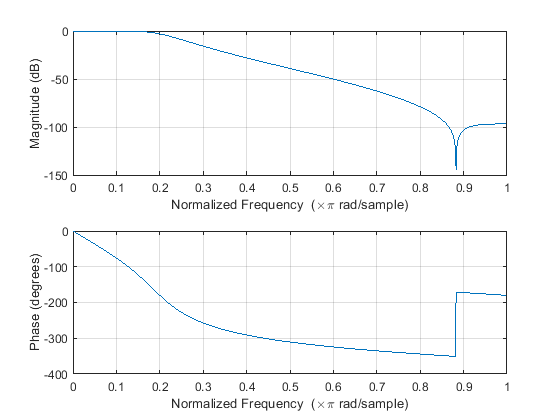

freqz(num,den)

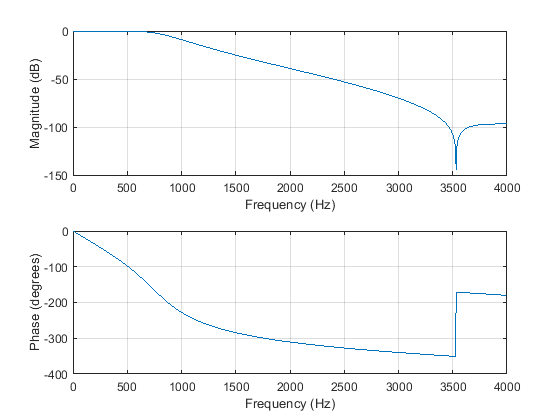


% Frekvensen er her normaliseret
% Den aktuelle samplingfrekvens introduceres
fs = 8000;
freqz(num,den,1024,fs)

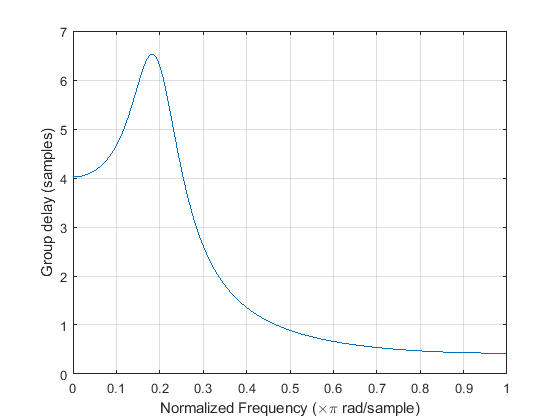


% Hvis man ligeledes prøver fs = 4000, halveres frekvensen.
% Tidsforsinkelsen findes med
grpdelay(num,den)

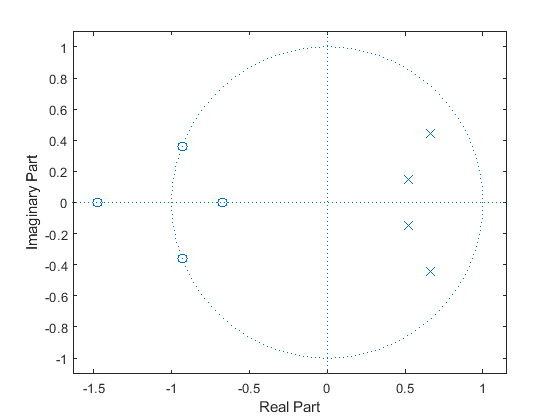

% Det digitale filter har ikke lineær fase.

% Afbildning af nulpunkter og poler
zplane(num,den)

% Idet alle poler inde i enhedscirklen, er systemet stabilt.

% Partialbrøkopløsning:
[r p k] = residuez(num,den)

r =   -0.2698 + 0.1343i
  -0.2698 - 0.1343i
   0.2594 - 0.8024i
   0.2594 + 0.8024i


p =    0.6604 + 0.4433i
   0.6604 - 0.4433i
   0.5243 + 0.1459i
   0.5243 - 0.1459i


k = 0.0256

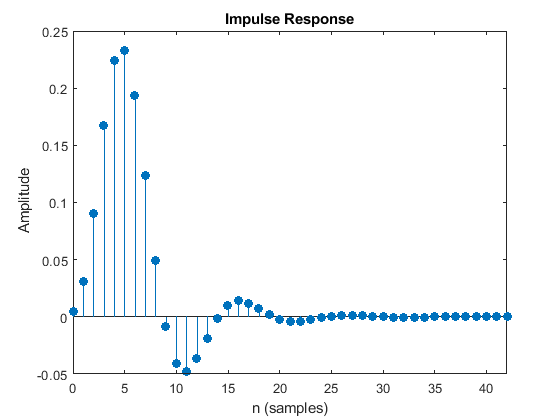


% Impuls- og step-svar
impz(num,den)

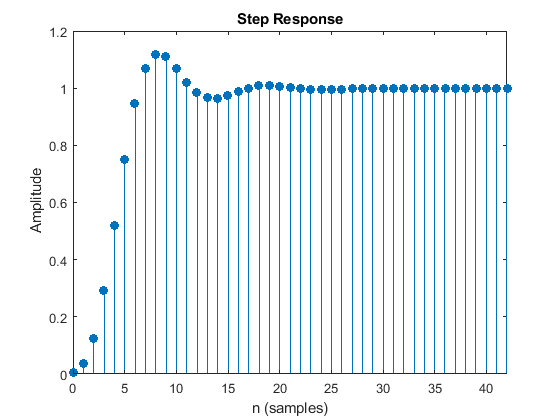

stepz(num,den)

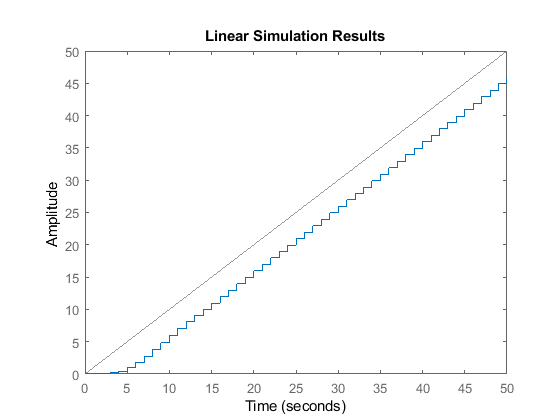

% Dette viser også, at systemet er stabilt.

% Systemsvar på vilkårligt input, f.eks. rampe, findes med lsim-funktionen
x = 0:1:50;
dlsim(num,den,x)

Ligeledes gennemføres systemanalyse af en anden overføringsfunktion:

num = [1];
den = [1 0 -4.25 0 1];

Hz = tf(num,den,1)


Hz =
 
          1
  ------------------
  z^4 - 4.25 z^2 + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



set(Hz,'variable','z^-1')

Hz


Hz =
 
          z^-4
  --------------------
  1 - 4.25 z^-2 + z^-4
 
Sample time: 1 seconds
Discrete-time transfer function.



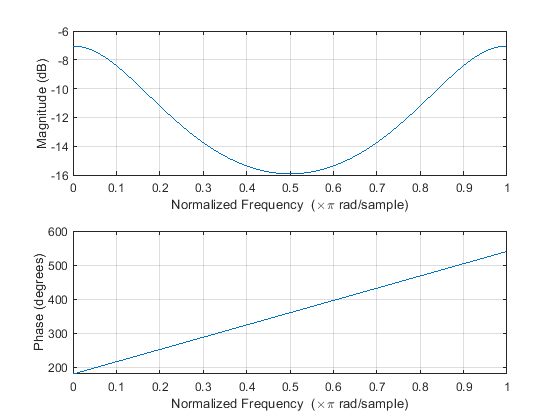

freqz(num,den)

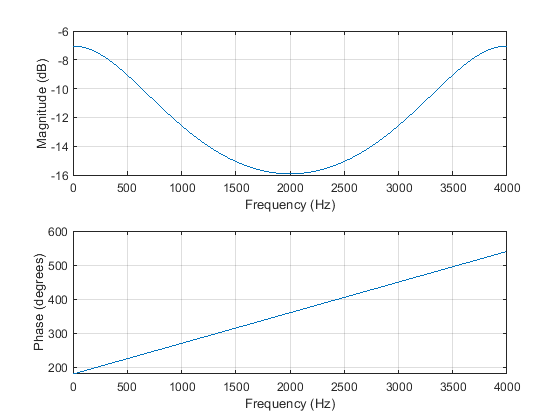


fs = 8000;
freqz(num,den,1024,fs)

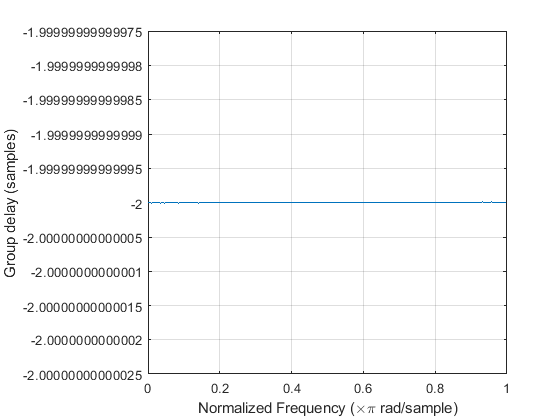


grpdelay(num,den)

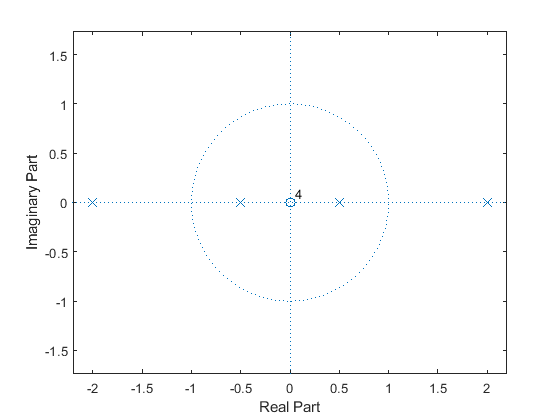


zplane(num,den)


[r p k] = residuez(num,den)

r =     0.5333
    0.5333
   -0.0333
   -0.0333


p =    -2.0000
    2.0000
   -0.5000
    0.5000



k =

     []



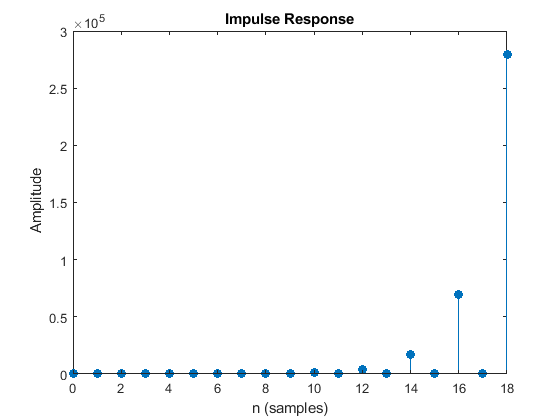

impz(num,den)

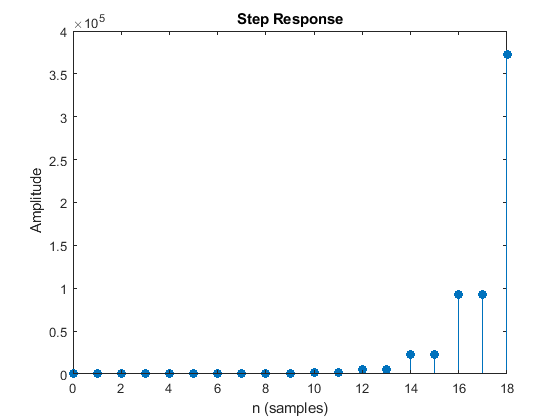

stepz(num,den)

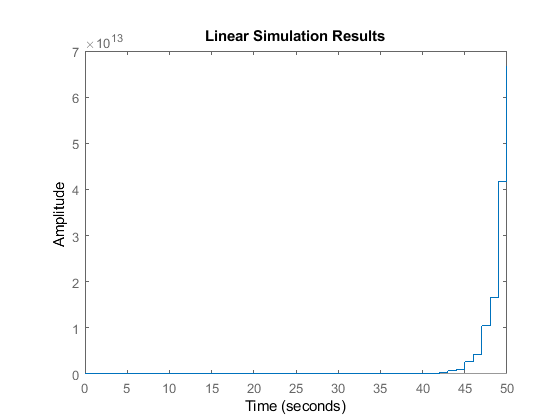

dlsim(num,den,x)

**Simpelt filterdesign:**

Filterdesign ud fra placering af poler og nulpunkter. Der ønskes et båndpasfilter omkring 1 kHz med en samplingfrekvens på 8 kHz. Der placeres derfor en pol ved pi/4 og overføringsfunktionen bestemmes.

b = 1;
help poly

 poly Convert roots to polynomial.
    poly(A), when A is an N by N matrix, is a row vector with
    N+1 elements which are the coefficients of the
    characteristic polynomial, det(lambda*eye(size(A)) - A).
 
    poly(V), when V is a vector, is a vector whose elements are
    the coefficients of the polynomial whose roots are the
    elements of V. For vectors, ROOTS and poly are inverse
    functions of each other, up to ordering, scaling, and
    roundoff error.
 
    Examples:
 
    roots(poly(1:20)) generates Wilkinson's famous example.
 
    Class support for inputs A,V:
       float: double, single
 
    See also roots, conv, residue, polyval.

    Reference page for poly
    

a = poly([0.707+0.707i 0.707-0.707i])

a =     1.0000   -1.4140    0.9997


Altså en overføringsfunktion: H(z) = 1 / (1 - 1.4*z^-1 + z^-2)

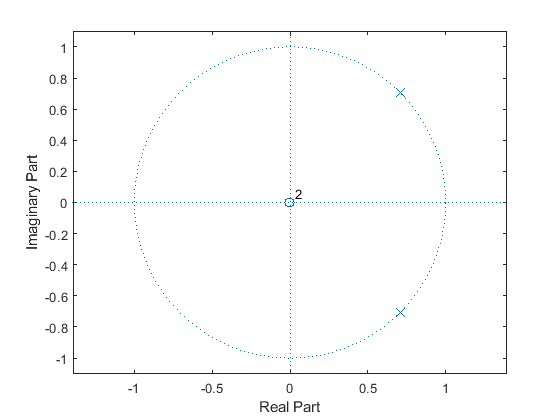

zplane(b,a)

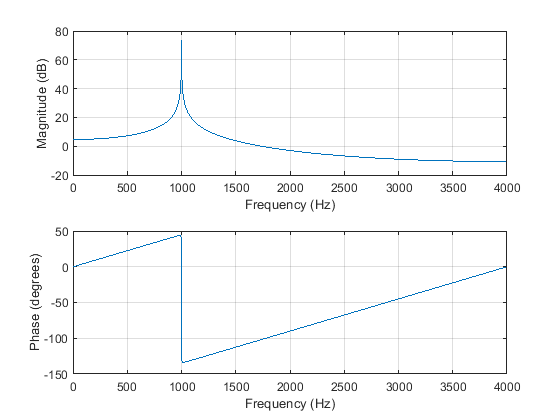


fs = 8000;
figure(2), freqz(b,a,1024,fs)

**Diskret foldning:**

Diskret foldning kan beregnes vha. conv-funktionen.

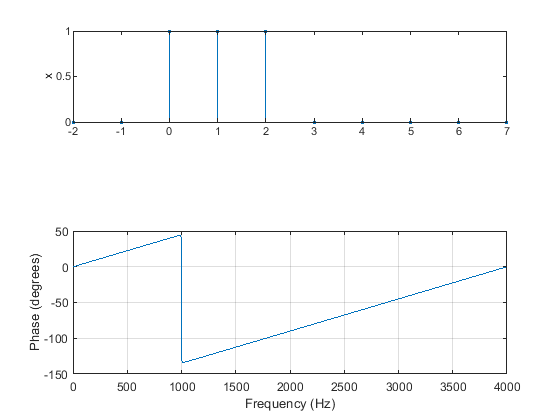

h = [1 1 1];
x = [1 1 1];
y = conv(h,x);
n = -2:7;
h = [0 0 h zeros(1,8-length(h))];
x = [0 0 x zeros(1,8-length(x))];
y = [0 0 y zeros(1,8-length(y))];

subplot(3,1,1), stem(n,x,'.'), ylabel('x')

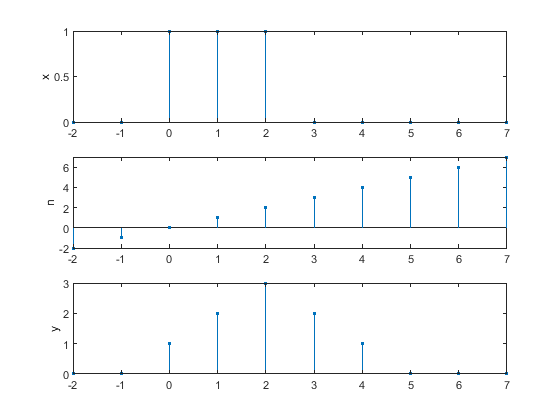

subplot(3,1,2), stem(n,n,'.'), ylabel('n')
subplot(3,1,3), stem(n,y,'.'), ylabel('y')

**Differensligning:**

Differensligningen y[n] = x[n] + x[n-1] + 0.5*y[n-1] kan for givet x[n] beregnes:

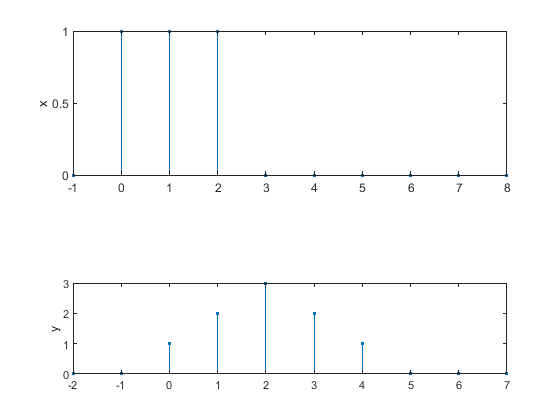

x = [0 1 1 1 0 0 0 0 0 0];
y = zeros(size(x));
for n = 2:10
    y(n) = x(n) + x(n-1) + 0.5*y(n-1);
end
n = -1:8;
subplot(2,1,1), stem(n,x,'.'), ylabel('x')

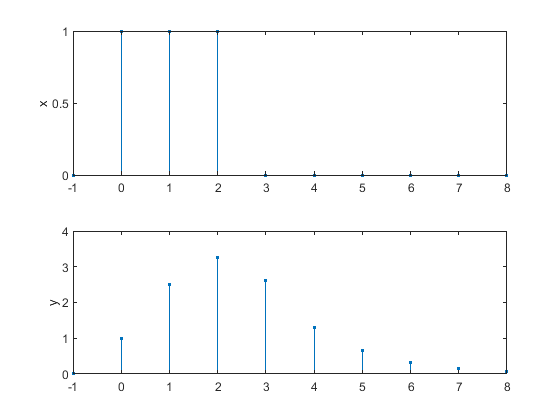

subplot(2,1,2), stem(n,y,'.'), ylabel('y')